## The three interpretations of a rotation matrix

### 1. Description of a frame

A rotation matrix provides the orientation of a frame with respect to the world frame (original frame). In this example, the original frame is rotated about the z-axis by 30 degrees to obtain the new frame. The following piece of code simply draws the axes (original and rotated). You can skip ahead, if you want (you'll understand the code by the end of this handout). 

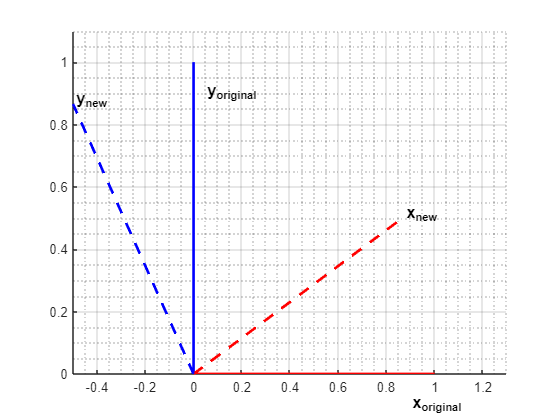

% Draw the original frame
f = figure;
% Set the axes limits
xlim([-0.5 1.3]);
ylim([0 1.1]);
zlim([0 2]);
% Grid Options
grid on;
grid minor;
% Draw x and y axes
line([0 1],[0 0],'color','red','LineWidth',2);
line([0 0],[0 1],'color','blue','LineWidth',2);
text(0.9,-0.1,'x_{original}','FontWeight',"bold",'FontSize',12);
text(0.05,0.9,'y_{original}','FontWeight',"bold",'FontSize',12);

% Draw the rotated frame
R = eul2rotm([deg2rad(30),0,0]); % This is the rotation matrix. 
% Find the x and y axis end-points after rotation
x_new = R*[1;0;0];
y_new = R*[0;1;0];
% Draw the new axes
line([0 x_new(1)],[0 x_new(2)],'color','red','LineWidth',2,'LineStyle','--');
line([0 y_new(1)],[0 y_new(2)],'color','blue','LineWidth',2,'LineStyle','--');
text(x_new(1)+0.01,x_new(2)+0.01,'x_{new}','FontWeight',"bold",'FontSize',12);
text(y_new(1)+0.01,y_new(2)+0.01,'y_{new}','FontWeight',"bold",'FontSize',12);

The rotation matrix describing the rotated frame is:

R

R =     0.8660   -0.5000         0
    0.5000    0.8660         0
         0         0    1.0000


Notice that the first column of this matrix is the new x unit vector expressed in the coordinates of the original frame. You can see this by finding the coordinates of the end point of the red dashed line in the original frame since the red dashed line has unit length. Similarly, the second column is the new y unit vector in the coordinates of the original frame. So, by looking at the columns you know where the axes of the new frame are or you have a complete description of the new frame. You can add datatips by clicking at the endpoint in the above figure or uncommenting the code below. 

% ax = gca;
% chart = ax.Children(4);
% datatip(chart,0.866,0.5);

### 2. Changing the coordinates of a point 

In our subscript/superscription notation of class, this rotation matrix will be expressed as ${}^0R_1$    , where 0 represents the original frame and 1 represents the rotated frame. So, it can be used to change the coordinates of any point expressed in frame 1 to the coordinates of the same point expressed in 0 frame. Let's consider a point p that is located on the new x-axis at a distance 0.8 from zero. So, its coordinates in the new frame are (0.8,0). 

What will be its coordinates in the 0 frame? We can find it out using the rotation matrix R.

p0 = R*[0.8;0;0]

p0 =     0.6928
    0.4000
         0


The point is indicated in the following plot. 

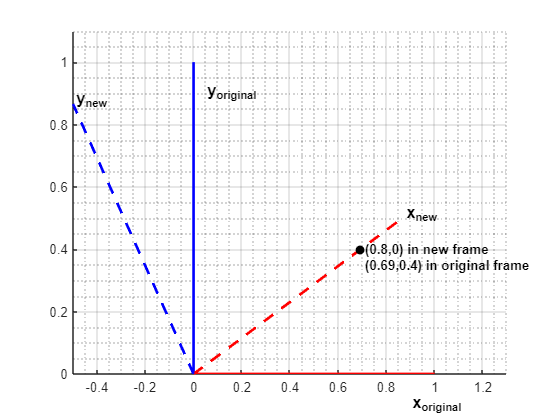

% Draw the original frame
f = figure;
% Set the axes limits
xlim([-0.5 1.3]);
ylim([0 1.1]);
zlim([0 2]);
% Grid Options
grid on;
grid minor;
% Draw x and y axes
line([0 1],[0 0],'color','red','LineWidth',2);
line([0 0],[0 1],'color','blue','LineWidth',2);
text(0.9,-0.1,'x_{original}','FontWeight',"bold",'FontSize',12);
text(0.05,0.9,'y_{original}','FontWeight',"bold",'FontSize',12);

% Draw the new axes
line([0 x_new(1)],[0 x_new(2)],'color','red','LineWidth',2,'LineStyle','--');
line([0 y_new(1)],[0 y_new(2)],'color','blue','LineWidth',2,'LineStyle','--');
text(x_new(1)+0.01,x_new(2)+0.01,'x_{new}','FontWeight',"bold",'FontSize',12);
text(y_new(1)+0.01,y_new(2)+0.01,'y_{new}','FontWeight',"bold",'FontSize',12);

% Indicate the point on the plot
line(p0(1),p0(2),'color','black','Marker','.','MarkerSize',20);
text(p0(1)+0.02,p0(2),'(0.8,0) in new frame','FontWeight',"bold",'FontSize',10);
text(p0(1)+0.02,p0(2)-0.05,'(0.69,0.4) in original frame','FontWeight',"bold",'FontSize',10);

### 3. Coordinates of a point in the same frame after rotation

The final use of rotation matrix is to obtain new coordinates of a point in the same frame after rotation. For example, consider the point P = (0.69,0.4) in the original frame. This is the same point at the same physical location as in the previous example.

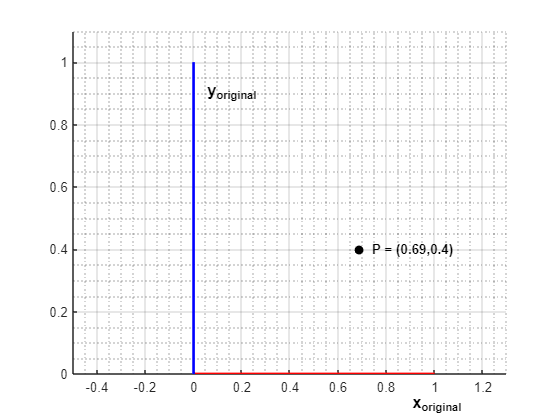

% Draw the original frame
f = figure;
% Set the axes limits
xlim([-0.5 1.3]);
ylim([0 1.1]);
zlim([0 2]);
% Grid Options
grid on;
grid minor;
% Draw x and y axes
line([0 1],[0 0],'color','red','LineWidth',2);
line([0 0],[0 1],'color','blue','LineWidth',2);
text(0.9,-0.1,'x_{original}','FontWeight',"bold",'FontSize',12);
text(0.05,0.9,'y_{original}','FontWeight',"bold",'FontSize',12);

% Indicate the point on the plot
P = [0.69;0.4;0];
line(P(1),P(2),'color','black','Marker','.','MarkerSize',20);
text(P(1)+0.05,P(2),'P = (0.69,0.4)','FontWeight',"bold",'FontSize',10);

The rotation matrix R corresponds to a rotation about z-axis by 30 degrees. What would happen to P after this rotation? 

P_new = R*P

P_new =     0.3976
    0.6914
         0


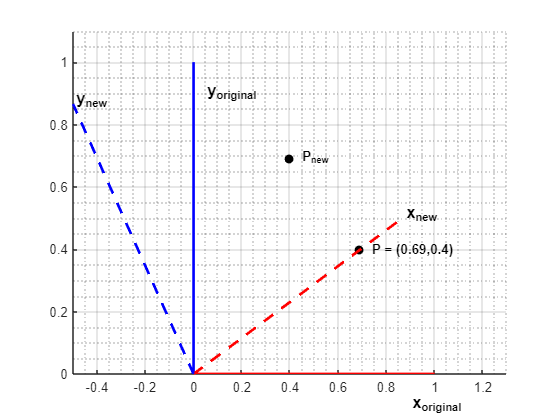


% Redraw the axes with new point
% Draw the original frame
f = figure;
% Set the axes limits
xlim([-0.5 1.3]);
ylim([0 1.1]);
zlim([0 2]);
% Grid Options
grid on;
grid minor;
% Draw x and y axes
line([0 1],[0 0],'color','red','LineWidth',2);
line([0 0],[0 1],'color','blue','LineWidth',2);
text(0.9,-0.1,'x_{original}','FontWeight',"bold",'FontSize',12);
text(0.05,0.9,'y_{original}','FontWeight',"bold",'FontSize',12);

% Indicate the original location of point on the plot
line(P(1),P(2),'color','black','Marker','.','MarkerSize',20);
text(P(1)+.05,P(2),['P = (',num2str(P(1)),',',num2str(P(2)),')'],'FontWeight',"bold",'FontSize',10);

% Indicate the new location of point on the plot
line(P_new(1),P_new(2),'color','black','Marker','.','MarkerSize',20);
text(P_new(1)+0.05,P_new(2),'P_{new}','FontWeight',"bold",'FontSize',10);
% Draw the new axes
line([0 x_new(1)],[0 x_new(2)],'color','red','LineWidth',2,'LineStyle','--');
line([0 y_new(1)],[0 y_new(2)],'color','blue','LineWidth',2,'LineStyle','--');
text(x_new(1)+0.01,x_new(2)+0.01,'x_{new}','FontWeight',"bold",'FontSize',12);
text(y_new(1)+0.01,y_new(2)+0.01,'y_{new}','FontWeight',"bold",'FontSize',12);

Note that in this case the coordinate are all expressed in the original frame. Otherwise, the coordinates of point after rotation in the new frame will have remained (0.69,0.4) as both the new frame and point have rotated by the same amount and are stationary with respect to each other.

## Concluding observation

Say we have a rotation matrix ${}^0R_1$ and a point P. Then for the same physical point P, if we express it in coordinates of frame 1, then $Rp= \,^0R_1\,^1p = \,^0p$, and we end up changing coordinates of P with R, but if we express p in frame 0, then $Rp = \,^0R_1\,^0p = \,^0p'$ and we end up rotating the point P to a new location P' and the location is expressed in the coordinates of the same frame 0. 